# Autorzy sprawozdania

Piotr Patek, 324 789

Damian Baraniak, 324 851

## Opis rozwiązania

Tym razem do analizy tętna wykorzystano transformatę fouriera. Analizując w ten sposób sygnał jesteśmy w stanie wyciągnąć poszczególne składowe częstotliwości które budują sygnał. Częstotliwość o największym wpływie przekonwertowana do jednostki uderzeń na minutę daje nam odczytane tętno.

% Parametry systemu
Fs = 1000;     % Częstotliwość próbkowania [Hz]
T = 1/Fs;      % Okres próbkowania [s]
L = 2000;      % Długość sygnału (liczba próbek)
t = (0:L-1)*T; % Podstawa czasu

% Przygotowanie sygnału
N = 3;               % Liczba sinusoid w mieszaninie
A = [1.0   0.4  0.8] % Amplitudy kolejnych sinusoid

A =     1.0000    0.4000    0.8000


B = [ 15    27   83] % Częstotliwości kolejnych sygnałów [Hz]

B =     15    27    83


C = [  0 -pi/3 pi/7] % Przesunięcia fazowe kolejnych sygnałów

C =          0   -1.0472    0.4488


x = zeros(size(t));
for i = 1:N
  x = x + A(i) * cos(2 * pi * B(i) * t + C(i));
end

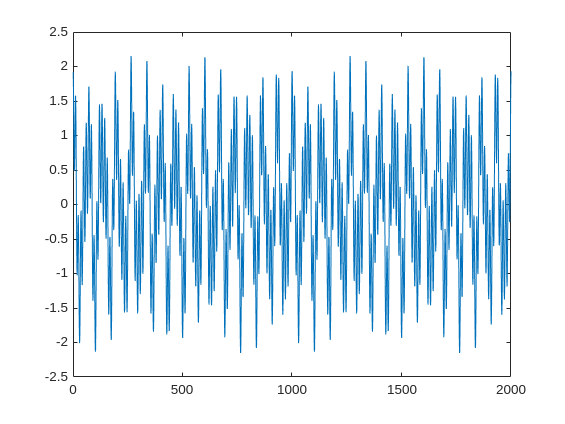

plot(x);

## FFT

Y = fft(x);     % transformata Fouriera

Amp = abs(Y);     % amplituda sygnału
Amp = Amp/L;        % normalizacja amplitudy



Amp = Amp(1:L/2+1); % wycięcie istotnej części spektrum
Amp(2:end-1) = 2*Amp(2:end-1);

Phi = angle(Y);   % faza sygnału
Phi = Phi(1:L/2+1); % wycięcie istotnej części spektrum


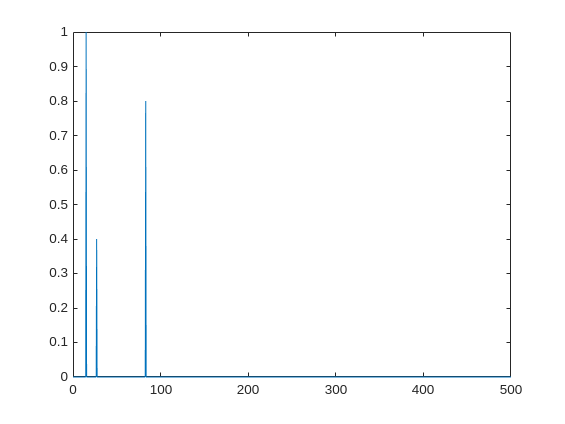

f_step = Fs/L;     % zmiana częstotliwości
f = 0:f_step:Fs/2; % oś częstotliwości do wykresu

figure;
plot(f, Amp);        % wykres amplitudowy

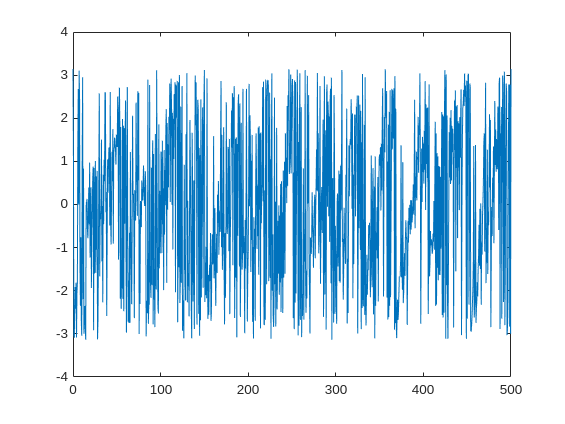


figure;
plot(f, Phi);        % wykres fazowy

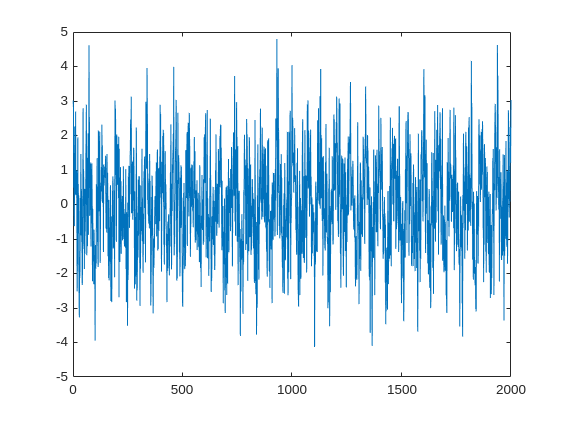

% Sygnał zaszumiony

x_noisy = x + randn(size(x));

plot(x_noisy);

Y_noisy = fft(x_noisy);     % transformata Fouriera

Amp_noisy = abs(Y_noisy);     % amplituda sygnału
Amp_noisy = Amp_noisy/L;        % normalizacja amplitudy



Amp_noisy = Amp_noisy(1:L/2+1); % wycięcie istotnej części spektrum
Amp_noisy(2:end-1) = 2*Amp_noisy(2:end-1);

Phi_noisy = angle(Y_noisy);   % faza sygnału
Phi_noisy = Phi_noisy(1:L/2+1); % wycięcie istotnej części spektrum


f_step = Fs/L;     % zmiana częstotliwości
f = 0:f_step:Fs/2; % oś częstotliwości do wykresu

figure;
plot(f, Amp);

[amps, frequencies] = maxk(Amp_noisy, 3)

amps =     1.0360    0.7707    0.4366


frequencies =     31   167    55


phases = angle(Y(frequencies));

new_x = zeros(size(t));
for i = 1:N
  new_x = new_x + amps(i) * cos(2 * pi * frequencies(i) * t + phases(i));
end

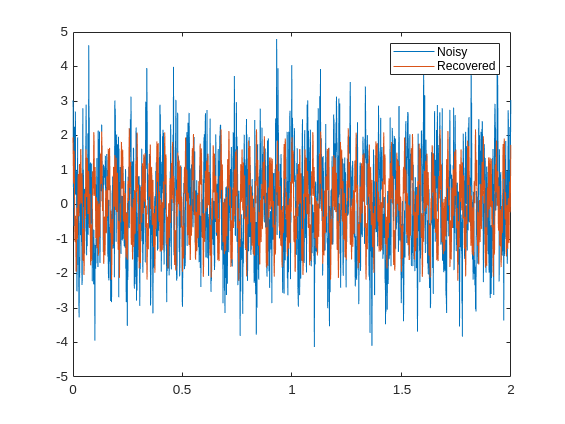

figure;
plot(t, x_noisy);
hold on;
plot(t, new_x);
legend("Noisy", "Recovered");

## Tetno


% Liczba ramek do wczytania (przy 10 sekundach i 30 FPS będzie to 300)
N = 600;

% wektor jasności
br = zeros(3, N);

use_video = 1;

if use_video
    % wczytywanie pliku wideo do analizy
    v = VideoReader(['../L1/data/IMG_5844.mp4']);
else
    % lista obrazów do analizy
    imds = imageDatastore('./data/', 'FileExtension', '.jpg');
end

% wczytanie pierwszych N obrazów i analiza jasności
for i=1:N

    if use_video
        % dla pliku wideo ładowanie ramki z otwartego źródła
        I = read(v,i);
    else
        % wczytujemy obraz
        I = imread(imds.Files{i});
    end

    h = size(I,1);
    w = size(I,2);

    % wybieramy jedynie czerwoną składową obrazu
    I = I(:,:,1);

    % jasność punktu na środku obrazu
    br(1, i) = I(h/2, w/2);

    % wyznaczamy średnią z całego obrazu
    br(2, i) = mean(I, 'all');
end

% dla ułatwienia późniejszej analizy od razu można odjąć od sygnału składową stałą
br = br - mean(br, 2);


tetno_y = fft(br(2, :));
tetno_amp = abs(tetno_y(1:length(tetno_y)/2+1)); % wycięcie istotnej części spektrum
tetno_amp(2:end-1) = 2*tetno_amp(2:end-1);

[~, BPM] = maxk(tetno_amp, 1);

disp(BPM*30/N*60);

    87



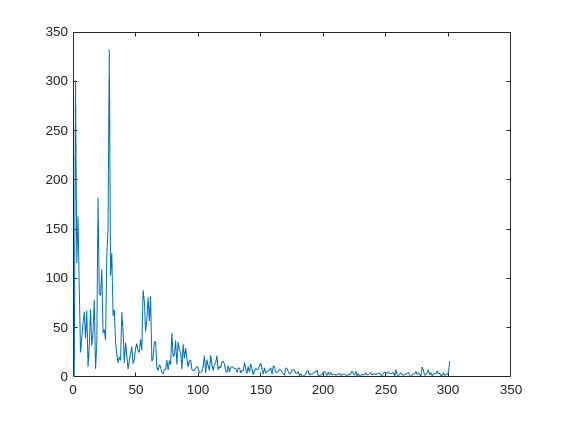

figure;
plot(tetno_amp);

## Analiza rozdzielczości

Rozdzielczość tej metody wynosi FPS/L czyli dla naszego pomiaru w 30 klatkach na sekundę i filmem o długości 20s dostajemy 600 klatek czyli 0.05. 

Jedną z metod poprawy rozdzielczości tego pomiaru byłoby wydłużenie długości pomiaru.